# VLP Simulations

This file performs the simulations for the following controllers to generate results for the thesis:

- The VNHC $l^\star(\theta)$ which corresponds to the time-optimal controller from the paper "Pumping a swing by standing and squatting".

- The VNHC $l_T(\theta)$ which is a continuous version of $l^\star(\theta)$.

- The VNHC $l(\theta) = -\Delta l \sin(2\theta) + l_\text{avg}$ which is the smooth version of $l^\star(\theta)$.

For each of these, we generate phase plots (q,p) for a multitude of VLPs. We also display the true mechanical energy $E(q,p) = \frac{p^2}{2ml^2} + (1-mgl\cos(\theta))$, as well as the anti-Lyapunov function $E_\text{avg}(q,p) = \frac{p^2}{2ml_\text{avg}^2} + (1-mgl_\text{avg}cos(\theta))$.

close all;
clc;

% Set the dynamic variables of the vlp
m = sym('m','positive'); % mass in kg
g = sym('g','positive'); % gravitational acceleration
l = sym('l','positive'); % length in m
q = sym('q','real'); % angle with respect to vertical line
p = sym('p','real'); % momentum of the mass
t = sym('t','real'); % angle theta in the (q,p) plane
% Define the energy
E = p^2/(2*m*l^2) + (1 - m*g*l*cos(q));
% Get the dynamics
qd = simplify(diff(E,p));
pd = simplify(-diff(E,q));
eom = [qd; pd];

% Set the physical parameters to test, as a struct array.
p1.m = 1;   p1.lu = 1; p1.lb = 3; 
    p1.init = [0.001;0]; p1.duration = 9;
    p1.T = 0.1;
p2.m = 0.5;  p2.lu = 1; p2.lb = 3;
    p2.init = [0.001;0]; p2.duration = 8;
    p2.T = 0.1;
vlps = [p1; 
       p2];
gravity = 9.81;

% Set the base options for the simulation
% Get the base options for plotting odes
baseOptions = odeset('RelTol',10^-14,'AbsTol',10^-14);

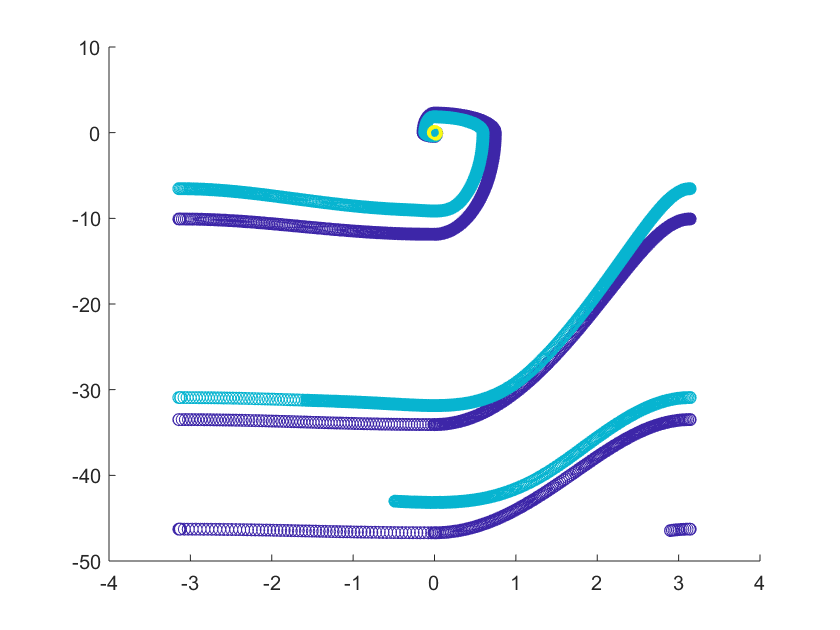

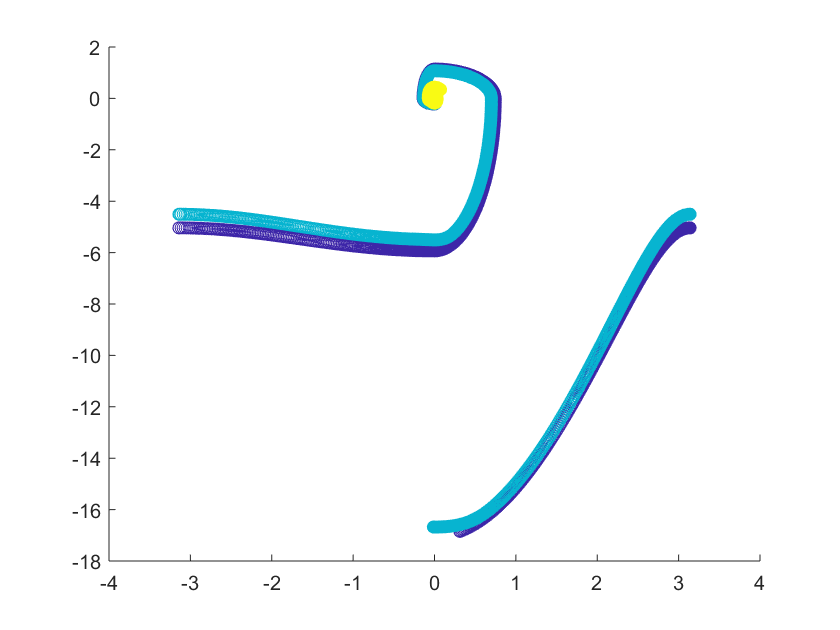

% Simulate the dynamics pf t he controllers
for i = 1:numel(vlps)
    vlp = vlps(i);
    % Input the current mass and gravity to test
    eom_a = matlabFunction(...
                subs(eom,[m g],[vlp.m gravity]),...
                'vars', [q p l]);
    % Compute the eom as a function for each controller
    eom_opt = @(q,p)eom_a(q,p,...
        vlp_l_optimal(atan2(p,q),vlp.lu,vlp.lb));
    eom_T = @(q,p)eom_a(q,p,...
        vlp_l_T(atan2(p,q),vlp.lu,vlp.lb,vlp.T));
    eom_smooth = @(q,p)eom_a(q,p,...
        vlp_l_smooth(atan2(p,q),vlp.lu,vlp.lb));
    % Simulate using ode45
    sol_opt = ode45(@(t,x)eom_opt(wrapToPi(x(1)),x(2)),...
         [0,vlp.duration],... % Time frame
         vlp.init,... % Initial Condition
         baseOptions);
     sol_T = ode45(@(t,x)eom_T(wrapToPi(x(1)),x(2)),...
         [0,vlp.duration],... % Time frame
         vlp.init,... % Initial Condition
         baseOptions);
     sol_smooth = ode45(@(t,x)eom_smooth(wrapToPi(x(1)),x(2)),...
         [0,vlp.duration],... % Time frame
         vlp.init,... % Initial Condition
         baseOptions);
     % Fix the solutions so they are on the cylinder
     sol_opt.y(1,:) = wrapToPi(sol_opt.y(1,:));
     sol_T.y(1,:) = wrapToPi(sol_T.y(1,:));
     sol_smooth.y(1,:) = wrapToPi(sol_smooth.y(1,:));
     % Compute the colour map to show how it flows
     c_opt = linspace(1,1,size(sol_opt.y,2));
     c_T = linspace(5,5,size(sol_T.y,2));
     c_smooth = linspace(10,10,size(sol_smooth.y,2));
     % Display the images on one plot
     figure;
     hold on;
     scatter(sol_opt.y(1,:),sol_opt.y(2,:),[],c_opt);
     scatter(sol_T.y(1,:),sol_T.y(2,:),[],c_T);
     scatter(sol_smooth.y(1,:),sol_smooth.y(2,:),[],c_smooth);
end